**16.1 특수 행렬**

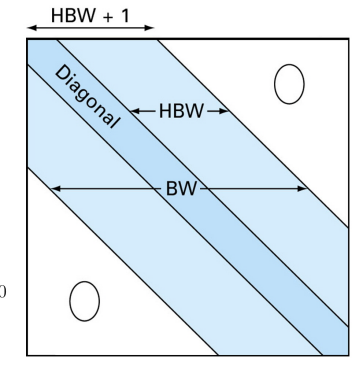

- **띠행렬 (banded matrix)**:띠행렬은 대각선을 중심으로 특정 범위 이내의 원소들만 값을 가지며, 그 외의 요소는 모두 0인 행렬입니다. 예시로 주어진 행렬은 다음과 같습니다.

$\left\lbrack \begin{array}{cccc}
1 & 2 & 0 & 0\\
1 & 2 & 3 & 0\\
0 & 1 & 4 & 2\\
0 & 0 & 3 & 2
\end{array}\right\rbrack$��

- **대역폭 (BW, Band Width)**:대각선을 기준으로 원소들이 값을 가지는 범위를 대역폭이라고 하며, 이는 $BW = 2 * HBW + 1$로 계산됩니다. HBW는 반대역폭(Half-BW)으로, 대각선으로부터 떨어진 행렬 요소의 최대 거리를 의미합니다.

- **대각행렬**:대각선을 제외한 나머지 원소가 모두 0인 행렬입니다.

- **효율적인 분해 방법**:띠행렬과 같은 특수 행렬의 경우, 일반적인 행렬 분해보다 Gauss 소거법이나 LU 분해를 사용하는 것이 더 효율적입니다. 이는 띠행렬에서 많은 원소들이 0이기 때문에 계산량이 줄어들기 때문입니다.

**16.2 Thomas 알고리즘**

**Thomas 알고리즘**은 **삼중 대각 시스템**에 대해 특화된 알고리즘입니다. 이는 대각선과 그 인접한 두 개의 대각선에만 값이 있는 삼중 대각 시스템을 해결하는데 사용됩니다.

**알고리즘 절차:**

- **분해 단계**:

$e_k = e_k / f_{k-1}, \quad f_k = f_k - e_k * g_{k-1}$�

- 여기서, $e_k, f_k, g_k$�는 시스템에서 사용되는 행렬 요소들입니다.

- **전진 대입 (Forward Substitution)**:


$$r_k = r_k - e_k * r_{k-1}$$


- �전진 대입 단계에서는 이전 단계의 값을 참조하여 행렬을 해결합니다.

- **후진 대입 (Backward Substitution)**:

$x_k = \frac{r_k}{f_k}, \quad x_k = (r_k - g_k * x_{k+1}) / f_k$�

- 후진 대입 단계에서 최종적으로 변수들을 계산하여 결과를 도출합니다.

이 알고리즘은 계산 비용이 삼중 대각 행렬의 구조를 고려해 효율적으로 이루어지며, 대규모 시스템에서도 유용하게 사용할 수 있습니다.

function x = thomas_algorithm(a, b, c, d)
    % a: 아래 대각선의 원소들 (n-1개의 원소)
    % b: 대각선 원소들 (n개의 원소)
    % c: 위 대각선의 원소들 (n-1개의 원소)
    % d: 우변 벡터 (n개의 원소)
    
    n = length(b);  % 행렬의 크기
    
    % 전진 대입 (Forward Elimination)
    for i = 2:n
        w = a(i-1) / b(i-1);
        b(i) = b(i) - w * c(i-1);
        d(i) = d(i) - w * d(i-1);
    end
    
    % 후진 대입 (Backward Substitution)
    x = zeros(n, 1);  % 결과 벡터 초기화
    x(n) = d(n) / b(n);  % 마지막 값 계산
    
    for i = n-1:-1:1
        x(i) = (d(i) - c(i) * x(i+1)) / b(i);
    end
    
    % 결과 출력
    disp('해결된 x 값:');
    disp(x);

    % 결과 시각화
    figure;
    plot(1:n, x, '-o', 'LineWidth', 2, 'MarkerSize', 8);
    title('Thomas 알고리즘에 의해 계산된 해');
    xlabel('x index');
    ylabel('x value');
    grid on;
end


해결된 x 값:
    1.0000
    1.0000
    1.0000
    1.0000



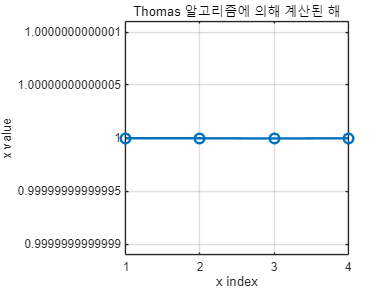

a = [-1, -1, -1];  % 아래 대각선
b = [2, 2, 2, 2];  % 주 대각선
c = [-1, -1, -1];  % 위 대각선
d = [1; 0; 0; 1];  % 우변 벡터


x = thomas_algorithm(a, b, c, d);

    1.0000
    1.0000
    1.0000
    1.0000



disp(x);

**문제**

주어진 삼중대각 행렬은 다음과 같습니다:

$\left\lbrack \begin{array}{cccc}
2\ldotp 04 & -1 & 0 & 0\\
-1 & 2\ldotp 04 & -1 & 0\\
0 & -1 & 2\ldotp 04 & -1\\
0 & 0 & -1 & 2\ldotp 04
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
40\ldotp 8\\
0\ldotp 8\\
0\ldotp 8\\
200\ldotp 8
\end{array}\right\rbrack$��

이는 삼중대각 행렬 시스템을 나타냅니다. 여기서 Thomas 알고리즘이나 LU 분해를 사용하여 해를 구할 수 있습니다.

**LU 분해 과정 설명**

- **LU 분해 정의**: 주어진 삼중대각 행렬을 두 개의 행렬 $L$ (하삼각행렬)과 $U$ (상삼각행렬)로 분해하는 과정입니다.


$$A = LU$$


- **행렬 요소 분해**: 각 단계에서 $L$과 $U$ 행렬의 요소를 차례로 계산해 나갑니다.

**계산 과정:**

- **1단계**:$e_2$는 두 번째 행의 첫 번째 요소를 나누어 계산됩니다.


$$e_2 = \frac{-1}{2.04} = -0.49$$


- $f_2$는 두 번째 행의 대각선 요소에서 앞서 계산한 $e_2$와 이전 행을 고려하여 계산됩니다.


$$f_2 = 2.04 - (-0.49)(-1) = 1.550$$


- **2단계**:마찬가지로 $e_3$와 $f_3$�를 계산합니다.


$$e_3 = \frac{-1}{1.550} = -0.645
$$



$$f_3 = 2.04 - (-0.645)(-1) = 1.395$$


- **3단계**:마지막으로 $e_4$�와 $f_4$�를 계산합니다.


$$e_4 = \frac{-1}{1.395} = -0.717
$$



$$f_4 = 2.04 - (-0.717)(-1) = 1.323$$


이 계산을 통해 $A$ 행렬을 $L$과 $U$로 분해할 수 있습니다. 분해된 행렬은 아래와 같습니다:

- **L 행렬** (하삼각행렬):

$L=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
-0\ldotp 49 & 1 & 0 & 0\\
-0\ldotp 645 & 0 & 1 & 0\\
-0\ldotp 717 & 0 & 0 & 1
\end{array}\right\rbrack$��

- **U 행렬** (상삼각행렬):

$U=\left\lbrack \begin{array}{cccc}
2\ldotp 04 & -1 & 0 & 0\\
0 & 1\ldotp 550 & -1 & 0\\
0 & 0 & 1\ldotp 395 & -1\\
0 & 0 & 0 & 1\ldotp 323
\end{array}\right\rbrack$��

**Thomas 알고리즘 적용**

- **전진 대입 (Forward Substitution)**:먼저 $L$ 행렬을 사용하여 중간 값을 계산합니다.


$$r_2 = 0.8 - (-0.49)(40.8) = 20.792           $$



$$r_3 = 0.8 - (-0.645)(20.792) = 14.208             $$



$$ r_4 = 200.8 - (-0.717)(14.208) = 210.984$$


- **후진 대입 (Backward Substitution)**:이제 $U$ 행렬을 사용하여 최종 해를 구합니다.


$$x_4 = \frac{210.984}{1.323} = 159.44                    $$



$$x_3 = \frac{14.208 - (-1)(159.44)}{1.395} = 124.24         $$



$$x_2 = \frac{20.792 - (-1)(124.24)}{1.550} = 93.58                     $$



$$x_1 = \frac{40.8 - (-1)(93.58)}{2.04} = 65.95$$


**최종 해:**


$$x_1 = 65.95, \quad x_2 = 93.58, \quad x_3 = 124.24, \quad x_4 = 159.44$$


% 주어진 삼중대각 행렬
n = 4;  % 행렬 크기
a = [-1, -1, -1];  % 아래 대각선
b = [2.04, 2.04, 2.04, 2.04];  % 주 대각선
c = [-1, -1, -1];  % 위 대각선
d = [40.8; 0.8; 0.8; 200.8];  % 우변 벡터

% 전진 대입 (Forward Elimination)
for i = 2:n
    m = a(i-1) / b(i-1);
    b(i) = b(i) - m * c(i-1);
    d(i) = d(i) - m * d(i-1);
end

% 후진 대입 (Backward Substitution)
x = zeros(n, 1);
x(n) = d(n) / b(n);

for i = n-1:-1:1
    x(i) = (d(i) - c(i) * x(i+1)) / b(i);
end

% 결과 출력
disp('해결된 x 값:')

해결된 x 값:


disp(x)

   65.9698
   93.7785
  124.5382
  159.4795



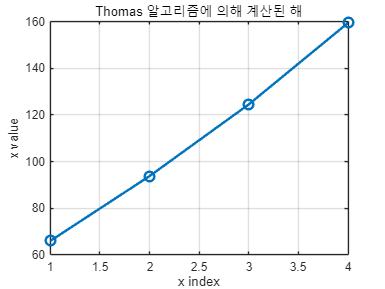


% 시각화
figure;
plot(1:n, x, '-o', 'LineWidth', 2, 'MarkerSize', 8);
title('Thomas 알고리즘에 의해 계산된 해');
xlabel('x index');
ylabel('x value');
grid on;

**전진 대입 (Forward Substitution)**

LU 분해를 통해 얻은 하삼각 행렬 L과 우변 벡터 B가 주어졌습니다. 이를 이용해 다음과 같은 관계식이 성립합니다:


$$LU \cdot X = B \Longrightarrow   L \cdot D = B$$


여기서 L은 하삼각 행렬이고, D는 중간 단계의 값을 포함한 벡터입니다. L을 사용하여 먼저 D 값을 계산합니다.

주어진 하삼각 행렬 L:

$L=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
-0\ldotp 49 & 1 & 0 & 0\\
-0\ldotp 645 & 0 & 1 & 0\\
-0\ldotp 717 & 0 & 0 & 1
\end{array}\right\rbrack$��

이를 전진 대입 공식에 따라 차례대로 해결합니다.

**계산 과정:**


$$r_2 = 0.8 - (-0.49) \cdot 40.8 = 20.8$$



$$r_3 = 0.8 - (-0.645) \cdot 20.8 = 14.221
$$



$$r_4 = 200.8 - (-0.717) \cdot 14.221 = 210.996$$


이 과정을 통해 $r_2, r_3, r_4$ �를 계산하였습니다. 이 값들은 후진 대입에서 사용할 중간 값입니다.

**후진 대입 (Backward Substitution)**

이제 상삼각 행렬 $U$와 중간 벡터 $r$를 사용하여 최종 해 $X$를 구하는 후진 대입을 수행합니다.

주어진 상삼각 행렬 $U$:

$U=\left\lbrack \begin{array}{cccc}
2\ldotp 04 & -1 & 0 & 0\\
0 & 1\ldotp 550 & -1 & 0\\
0 & 0 & 1\ldotp 395 & -1\\
0 & 0 & 0 & 1\ldotp 323
\end{array}\right\rbrack$��

**후진 대입 공식:**

$x_k = \frac{r_k - g_k \cdot x_{k+1}}{f_k}$��

이 공식을 이용해 차례로 $x_4$�부터 $x_1$까지 계산합니다.

**계산 과정:**


$$x_4 = \frac{210.996}{1.323} = 159.480$$



$$x_3 = \frac{14.221 - (-1) \cdot 159.480}{1.395} = 124.538
$$



$$x_2 = \frac{20.800 - (-1) \cdot 124.538}{1.550} = 93.778
$$



$$x_1 = \frac{40.800 - (-1) \cdot 93.778}{2.040} = 65.970$$


**최종 해:**

계산 결과 최종 해는 다음과 같습니다:


$$x_1 = 65.970, \quad x_2 = 93.778, \quad x_3 = 124.538, \quad x_4 = 159.480$$


**16.3 Cholesky 분해법**

- **대칭행렬**

- 주어진 행렬 $A$가 대칭행렬인 경우, 즉 $a_{ij} = a_{ji}$�인 경우 Cholesky 분해법을 사용할 수 있습니다.대칭행렬은 수학 및 공학 문제에서 자주 발생하며, Cholesky 분해법은 특히 저장 장소가 적고 계산량이 적어 시간 절감의 이점이 큽니다.

- **Cholesky 분해**

- Cholesky 분해는 행렬 $A$를 다음과 같이 두 개의 행렬 $L$과 $L^T$의 곱으로 분해합니다:


$$A = LL^T$$


- 여기서 $L$은 하삼각행렬이고, $L^T$는 그 전치행렬입니다.각 요소는 다음과 같이 계산됩니다:

- $l_{ki}$�는 $A$의 해당 요소에서 $L$ 행렬의 이미 계산된 값을 사용하여 구합니다.

$l_{ki} = \frac{a_{ki} - \sum_{j=1}^{k-1} l_{ij} l_{kj}}{l_{ii}}$��

- 대각선 성분은 다음과 같이 계산됩니다.

$l_{kk} = \sqrt{a_{kk} - \sum_{j=1}^{k-1} l_{kj}^2}$��

**Cholesky 분해 예시**

주어진 대칭행렬 $A$는 다음과 같습니다:

$A=\left\lbrack \begin{array}{ccc}
6 & 15 & 55\\
15 & 55 & 225\\
55 & 225 & 979
\end{array}\right\rbrack$��

Cholesky 분해를 수행하여 하삼각행렬 $L$을 구하는 과정입니다. $L$을 구하는 과정은 다음과 같습니다.

**단계별 계산 과정**

- **첫 번째 대각 성분 계산**:


$$l_{11} = \sqrt{6} \approx 2.4495$$


- **첫 번째 열의 나머지 값 계산**:


$$l_{21} = \frac{15}{2.4495} \approx 6.1237           $$



$$  l_{31} = \frac{55}{2.4495} \approx 22.454$$


- **두 번째 대각 성분 계산**:


$$l_{22} = \sqrt{55 - (6.1237)^2} \approx 4.1833$$


- **두 번째 열의 나머지 값 계산**:


$$l_{32} = \frac{225 - 6.1237 \times 22.454}{4.1833} \approx 20.917$$


- **세 번째 대각 성분 계산**:


$$l_{33} = \sqrt{979 - (22.454)^2 - (20.917)^2} \approx 6.1101$$


**최종 하삼각행렬 **$L$

따라서, 최종적으로 구한 하삼각 행렬 $L$은 다음과 같습니다:

$L=\left\lbrack \begin{array}{ccc}
2\ldotp 4495 & 0 & 0\\
6\ldotp 1237 & 4\ldotp 1833 & 0\\
22\ldotp 454 & 20\ldotp 917 & 6\ldotp 1101
\end{array}\right\rbrack$��

이 하삼각 행렬을 사용하여 $A$를 $L$과 $L^T$의 곱으로 분해한 결과는 다음과 같습니다:


$$A = LL^T$$


이로써 Cholesky 분해법을 사용하여 주어진 대칭행렬의 분해를 완료하였습니다.

**Cholesky 분해의 장점**

- 대칭행렬에서만 사용 가능하지만, 대칭 행렬의 성질을 이용해 계산 효율성이 높습니다.

- 특히 저장공간이 적게 들고 계산 과정에서 시간 절약이 가능합니다.

Cholesky 분해 후 L 행렬:
    2.4495         0         0
    6.1237    4.1833         0
   22.4537   20.9165    6.1101

해결된 x 값:
   50.9714
  -50.3543
    8.9143



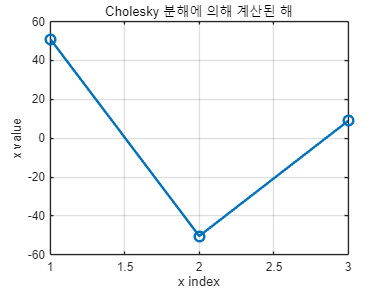

function x = cholesky_decomposition_example()
    % 주어진 대칭 행렬 A
    A = [6, 15, 55;
         15, 55, 225;
         55, 225, 979];
    
    % 우변 벡터 (임의 설정)
    b = [40.8; 0.8; 200.8];
    
    % 행렬 크기
    n = size(A, 1);

    % 하삼각 행렬 L 계산
    L = zeros(n, n); % L 행렬 초기화

    for i = 1:n
        % 대각 성분 계산
        L(i, i) = sqrt(A(i, i) - sum(L(i, 1:i-1).^2));
        
        % 비대각 성분 계산
        for j = i+1:n
            L(j, i) = (A(j, i) - sum(L(j, 1:i-1) .* L(i, 1:i-1))) / L(i, i);
        end
    end

    % 전진 대입 (Forward Substitution): L * y = b
    y = zeros(n, 1); % y 초기화
    for i = 1:n
        y(i) = (b(i) - L(i, 1:i-1) * y(1:i-1)) / L(i, i);
    end

    % 후진 대입 (Backward Substitution): L^T * x = y
    x = zeros(n, 1); % x 초기화
    for i = n:-1:1
        x(i) = (y(i) - L(i+1:n, i)' * x(i+1:n)) / L(i, i);
    end

    % 결과 출력
    disp('Cholesky 분해 후 L 행렬:');
    disp(L);

    disp('해결된 x 값:');
    disp(x);

    % 시각화
    figure;
    plot(1:n, x, '-o', 'LineWidth', 2, 'MarkerSize', 8);
    title('Cholesky 분해에 의해 계산된 해');
    xlabel('x index');
    ylabel('x value');
    grid on;
end


% Cholesky 분해 예시 실행
x = cholesky_decomposition_example();

Cholesky 분해 후 L 행렬:
    2.4495         0         0
    6.1237    4.1833         0
   22.4537   20.9165    6.1101

해결된 x 값:
   -0.5000
    0.9214
   -0.1786



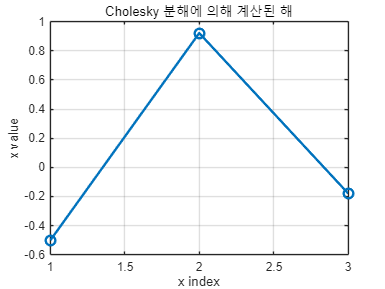

function x = cholesky_decomposition(A, b)
    % A: 대칭 행렬 (양의 정부호)
    % b: 선형 시스템의 우변 벡터

    % 행렬의 크기
    n = size(A, 1);

    % 하삼각 행렬 L 계산
    L = zeros(n, n); % L 행렬 초기화

    for i = 1:n
        % 대각 성분 계산
        L(i, i) = sqrt(A(i, i) - sum(L(i, 1:i-1).^2));
        
        % 비대각 성분 계산
        for j = i+1:n
            L(j, i) = (A(j, i) - sum(L(j, 1:i-1) .* L(i, 1:i-1))) / L(i, i);
        end
    end

    % 전진 대입 (Forward Substitution): L * y = b
    y = zeros(n, 1); % y 초기화
    for i = 1:n
        y(i) = (b(i) - L(i, 1:i-1) * y(1:i-1)) / L(i, i);
    end

    % 후진 대입 (Backward Substitution): L^T * x = y
    x = zeros(n, 1); % x 초기화
    for i = n:-1:1
        x(i) = (y(i) - L(i+1:n, i)' * x(i+1:n)) / L(i, i);
    end

    % 결과 출력
    disp('Cholesky 분해 후 L 행렬:');
    disp(L);

    disp('해결된 x 값:');
    disp(x);

    % 시각화
    figure;
    plot(1:n, x, '-o', 'LineWidth', 2, 'MarkerSize', 8);
    title('Cholesky 분해에 의해 계산된 해');
    xlabel('x index');
    ylabel('x value');
    grid on;
end

% 사용 예시
A = [6, 15, 55; 
     15, 55, 225; 
     55, 225, 979];  % 대칭 행렬 (양의 정부호)
b = [1; 3; 5];  % 우변 벡터


% Cholesky 분해 함수 호출
x = cholesky_decomposition(A, b);

